Since 20220727, I have been doing simulation of FLP with modified version (like change the population of 256 channels to 512 channels, detailed changes see the script /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220727.mlx). And for the results of the threshold of photon counts, I've seen very different results. To figure out why it's the case, I need to just change one thing at a time to figure out why it's causing all these difference. This time I'm using the same tau1 and tau2, same autofluorescence, DC, and afterpulse for the simulation, basically repeat the simulation of /Users/mapingchuan/Desktop/ChenLab_Data/MATLAB analysis/FLP_simulation_20220326.mlx with just different tau1 and tau2.

% Load the simulated data


p1_samples=0.6:0.02:1.0; % sumulated p1
AF=20000;
tau1=2.6199;
tau2=0.9221; % ACh sensor tau2
ch=1;
tau3=2.4922; % autofluorescence tau1
p3=0.2700; % autofluorescence p1
tau4=0.4069; % autofluorescence tau2
p4=0.7300; % autofluorescence p2

SS_samples=20000:20000:500000; % simulated sample size (photon count)



% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the p1 conditions
for i=1:21
    p1=p1_samples(i);
    eval(['tau_empTrunc_',num2str(i),'=[];'])
    for j=1:25
        SS=SS_samples(j);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(i),'=[tau_empTrunc_',num2str(i),' tau_empTrunc];'])
    end
end

% Collecting the results of calculated tau_empTrunc from the simulated
% samples, based on the sample size conditions

for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'=[];'])
    
    for i=1:21
        p1=p1_samples(i);
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name);
        eval(['tau_empTrunc_',num2str(SS),'=[tau_empTrunc_',num2str(SS),' tau_empTrunc];'])
    end
end

% calculate the mean and std for each simulated conditions

std_all=[];
mean_all=[]; % both of them will be a 25 x 21 matrix; row represents photon count and column represents p1

for i=1:25
    SS=SS_samples(i);
    eval(['this_samplesize=tau_empTrunc_',num2str(SS),';'])
    std_all=[std_all;std(this_samplesize)];
    mean_all=[mean_all;mean(this_samplesize)];
end

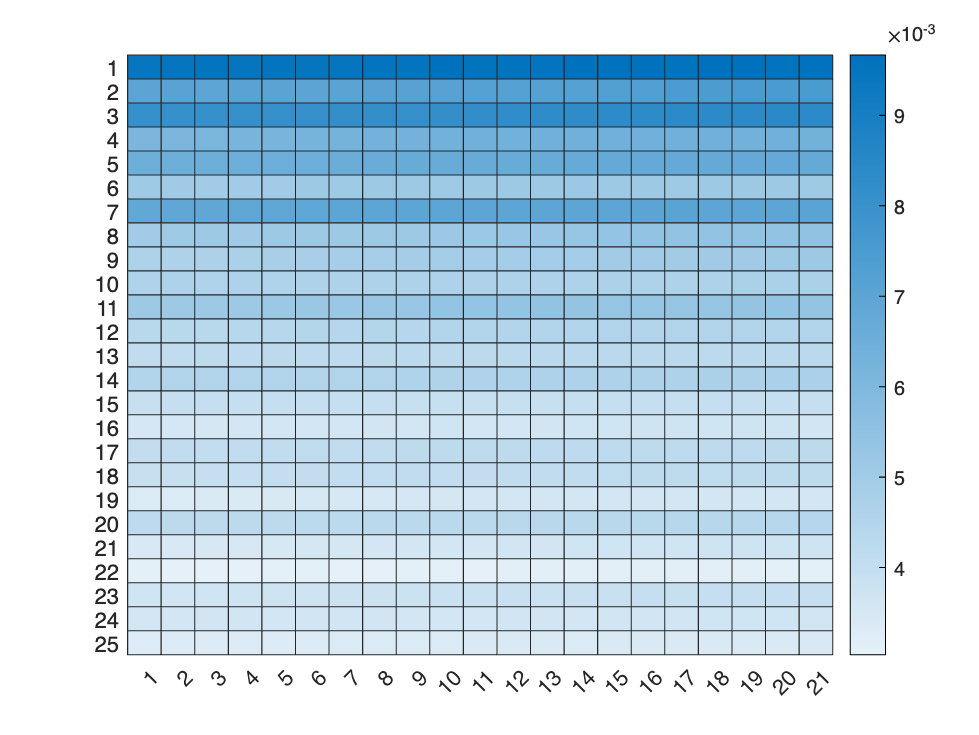

% plot the heatmap of mean and std of each condition
figure
heatmap(std_all)

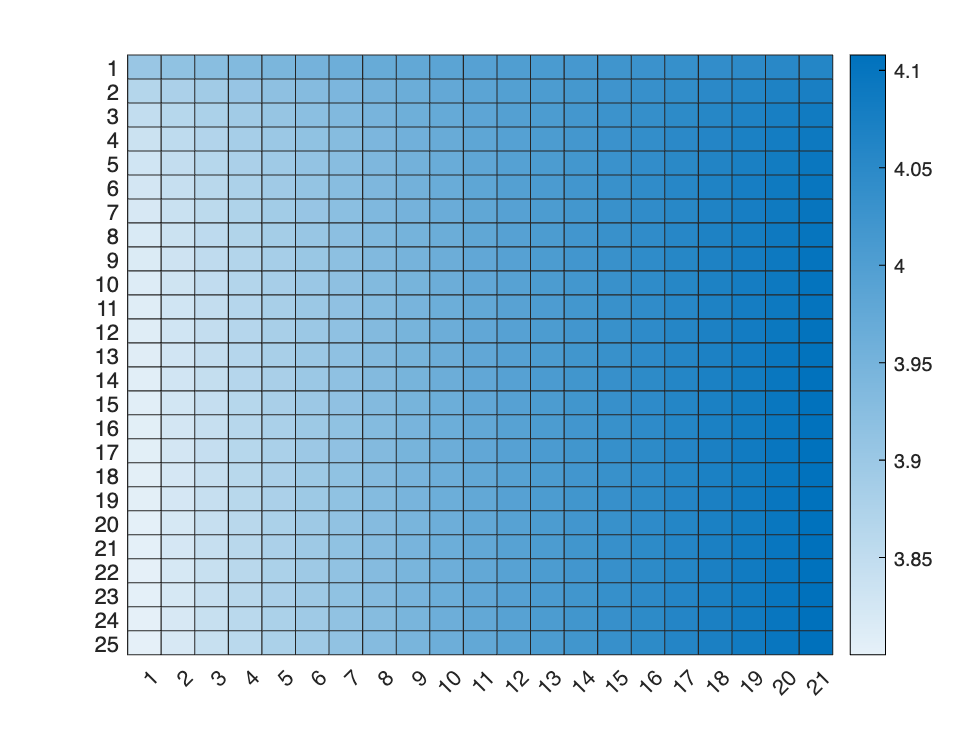

figure
heatmap(mean_all)

Ideally we want to ask whether a certain amount of lifetime change could be detected under different photon count conditions. However, what's under control is the p1 value in the simulation.

This section is trying to decide when p1 changes, whether that change could be detected under different photon count conditions, and transform that p1 change into lifetime change.

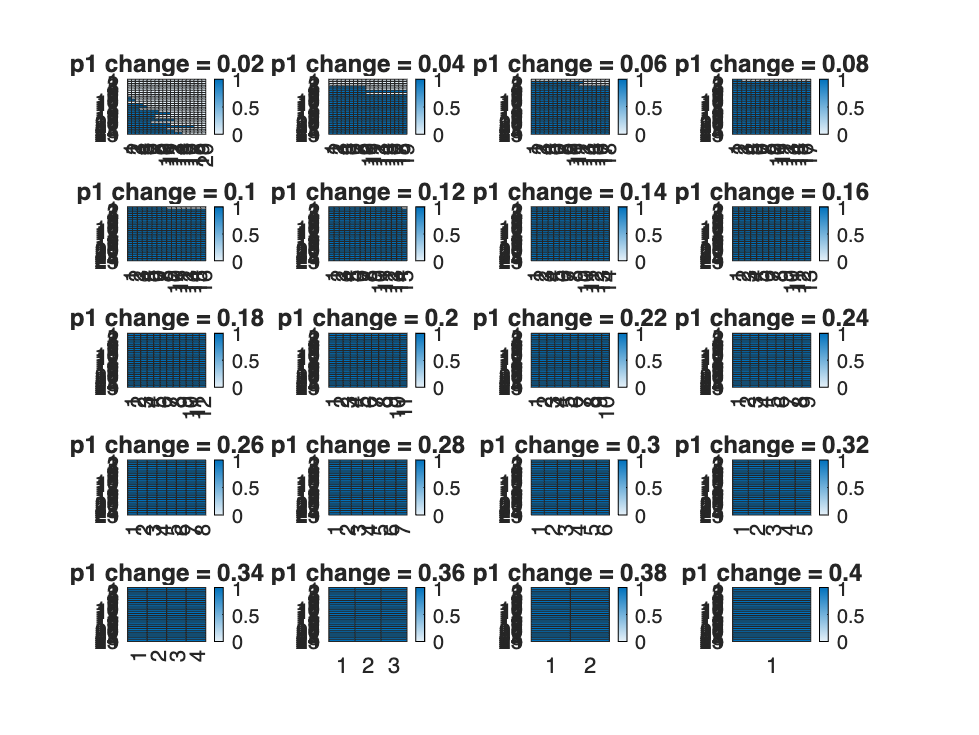

for j=1:20 % With different amount of p1 change; j*0.02 is the p1 change
    mean_all_diff=zeros(25,21-j); 
    for i=1:21-j
        mean_all_diff(:,i)=mean_all(:,i+j)-mean_all(:,i); % calculate the mean difference between columns (p1)
    end
%     figure
%     h1=heatmap(mean_all_diff);
    diff=mean_all_diff/3.96-std_all(:,1:(21-j)); % power check
    diff_plot=diff;
    diff_plot(find(diff>=0))=1; % if diff>0, difference can be detected
    diff_plot(find(diff<0))=0; % if diff>0, difference can't be detected
    eval(['diff_plot_',num2str(j),'=diff_plot;'])

    subplot(5,4,j)
    h=heatmap(diff_plot);
    h.Title=['p1 change = ',num2str(0.02*j)];
    h.ColorLimits=[0 1];
end

As mentioned before, in the matrix, the rows (lines) represent photon count. This section output with different amount of p1 change, under which line the difference starts to get detected.

for i=1:20
    eval(['diff_plot=diff_plot_',num2str(i),';'])
    minimum_line=NaN(1,20);
    for j=1:size(diff_plot,2)
        for k=1:25
            if diff_plot(26-k,j)==0 % starting from the last line the upwards, the first 0 value represent the difference starts not to get detected
                minimum_line(j)=26-k+1;
                break
            end
            if k==25 % if it's the last k (the first line, minimum photon count), then this smallest photon count is the threshold
                minimum_line(j)=1;
            end

        end
    end
    eval(['minimum_line_',num2str(i),'=minimum_line;'])
end

% pool all the minimum line together.
minimum_line_all=[];
for i=1:20
    eval(['minimum_line_all=[minimum_line_all;minimum_line_',num2str(i),'];'])
end


% plot the heatmap of the minimum line information. Each row represent the p1 change, each colunm represent
% the starting p1. The colors and numbers in the heatmap represent the
% minimum photon count (shown in line number) to detect that p1 change.
figure
h=heatmap(minimum_line_all)

h =   HeatmapChart with properties:

        XData: {20×1 cell}
        YData: {20×1 cell}
    ColorData: [20×20 double]

  Show all properties


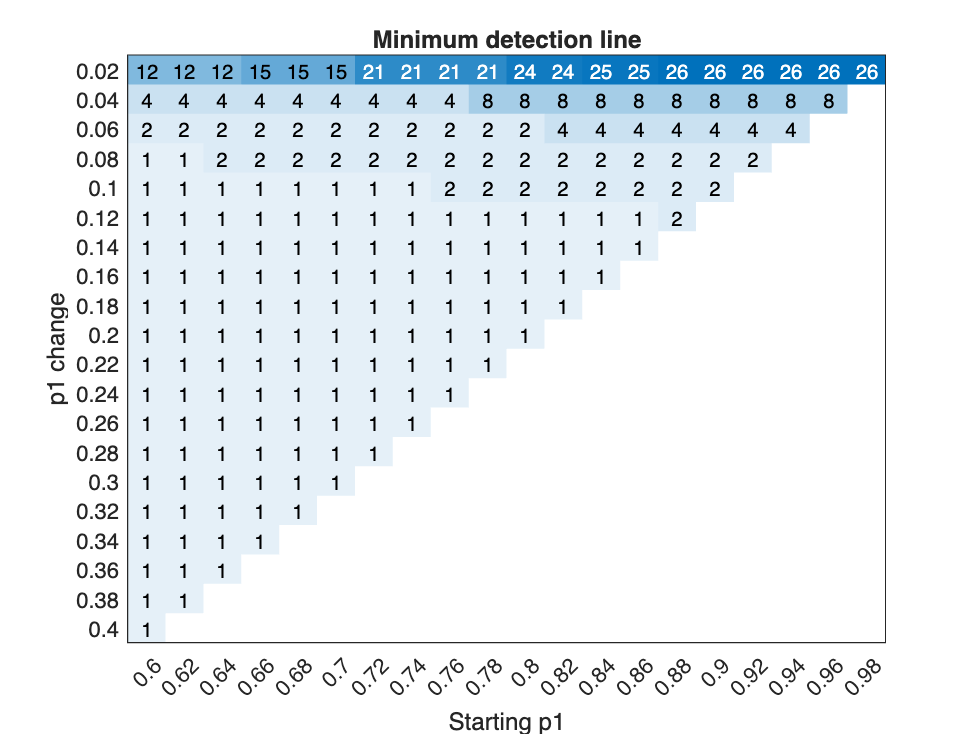

h.XLabel='Starting p1';
xlabelstrings=strings;
for i=1:20
    xlabelstrings(i)=num2str(0.6+(i-1)*0.02);
end
ylabelstrings=strings;
for i=1:20
    ylabelstrings(i)=num2str(0.02*i);
end

h.XDisplayLabels=xlabelstrings;
h.YDisplayLabels=ylabelstrings;
h.YLabel='p1 change';
h.MissingDataColor='white';
h.GridVisible='off';
h.Title="Minimum detection line";
h.ColorbarVisible='off';

Next I need to transform the p1 change to lifetime change. 

- One possibility is analytically calculate with this amount of p1 change, in theory how much of lifetime it should be. Due to autofluorescence etc., it will not be the case. 

- Another possibility is to empirically compare the mean difference from the simulation. Then under different photon count condition that mean difference will be different. To be conservative, use the maximum of these changes as the lifetime change to detect.

% possibility 1: analytically calculate the lifetime change with p1 change
for i=1:20
    lft_ends=NaN(1,20);
    
    p1_start=p1_samples(i);
    lft_start=(tau1*tau1*p1_start + tau2*tau2*(1-p1_start))/(tau1*p1_start + tau2*(1-p1_start));
    for j=1:21-i
        p1_end=p1_start+0.02*j;
        lft_end=(tau1*tau1*p1_end + tau2*tau2*(1-p1_end))/(tau1*p1_end + tau2*(1-p1_end));
        lft_end=lft_end-lft_start; % lifetime at changed p1 - lifetime at starting p1
        lft_ends(j)=lft_end;
    end
    
    eval(['lft_ends_',num2str(i),'=lft_ends;'])
end


% Possiblity 2: empirically calculat the mean difference and use the
% maximum for all photon count conditions.

for i=1:20
    lft_change=NaN(1,20);
    for j=1:21-i
        lft_change(j)=max(mean_all(:,i+j)-mean_all(:,i)); % maximum across all phton count conditions
    end
    eval(['lft_change_',num2str(i),'=lft_change;'])
end

% for i=1:20
%     lft_change=NaN(1,20);
%     for j=1:21-i
%         if minimum_line_all(j,i)-1>1
%            lft_change(j)=mean_all(minimum_line_all(j,i)-1,i+j)-mean_all(minimum_line_all(j,i)-1,i);
%         end
%         if minimum_line_all(j,i)-1==1
%             lft_change(j)=mean_all(1,i+j)-mean_all(1,i);
%         end
% 
%     end
%     eval(['lft_change_',num2str(i),'=lft_change;'])
% end


% plot the transformed lifetime chang with the minimum photon count needed
% to detect that change.
for i=1:19
    eval(['lft_plots1=lft_change_',num2str(i),';'])
    eval(['lft_plots2=lft_ends_',num2str(i),';'])
    subplot(5,4,i)
    plot(lft_plots1,(minimum_line_all(:,i)*20000));
    hold on
    plot(lft_plots2,(minimum_line_all(:,i)*20000));
    eval(['title("starting p1=',num2str(0.6+(i-1)*0.02),'")'])
    ylabel('photon count')
    xlabel('lifetime change')
    legend('simulated','analytical')
    hold off
end

subplot(5,4,20)
scatter(lft_change_20(1),minimum_line_all(1,20)*20000)
hold on
scatter(lft_ends_20(1),minimum_line_all(1,20)*20000)
ylabel('photon count')
xlabel('lifetime change')
legend('simulated','analytical')
hold off


The next section is trying to answer the 3rd question. How much photon count we can tolerate, which means with what amount of photon count we can not detect this photon count induced lifetime. Under different baseline photon count conditions that threshold will be different.

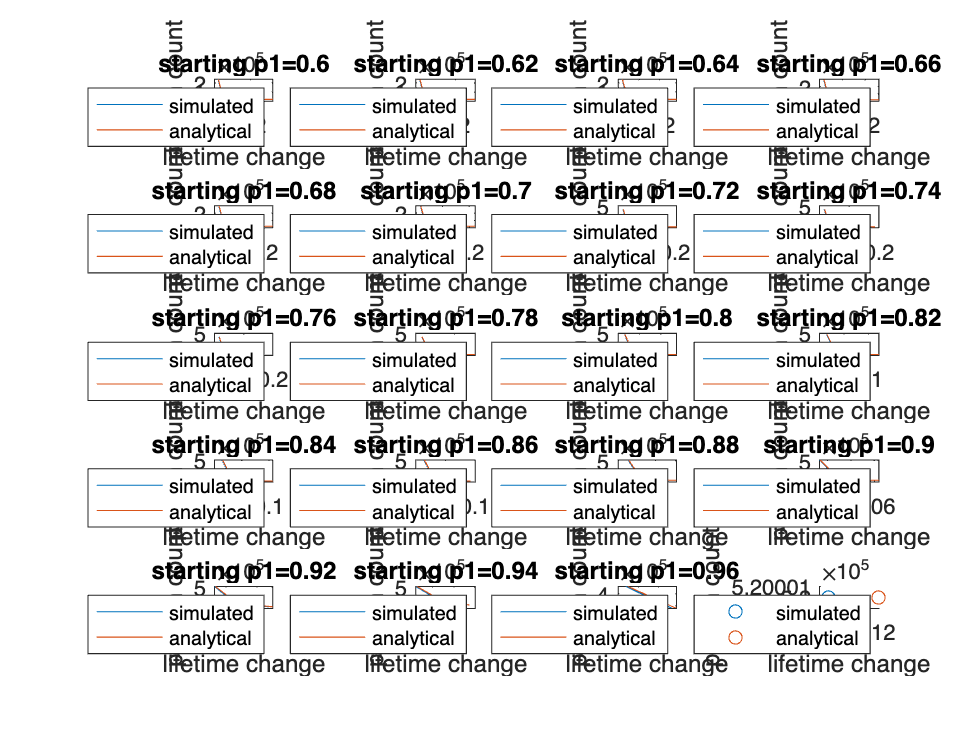

% instead of comparing the mean difference between different columns (p1) in the last session, we

% compare the mean difference between rows and test whether that difference
% is detectable.

detectable_line_all=[];
for j=1:24
    mean_all_diff2=zeros(25-j,21);
    for i=1:25-j
        mean_all_diff2(i,:)=mean_all(i+j,:)-mean_all(i,:); % calculate mean difference
    end
    diff=mean_all_diff2/3.96-std_all(1:25-j,:);
    diff_plot=diff;
    diff_plot(find(diff>=0))=1; % detectable
    diff_plot(find(diff<0))=0; % not detectable
%     subplot(6,4,j)
%     h=heatmap(diff_plot);
%     h.Title=['photon change = ',num2str(j*20000)];
%     h.ColorLimits=[0 1];

    detectable_line=[];
    for k=1:21
        for ii=1:25-j
            if diff_plot(ii,k)==0
                detectable_line(k)=ii; % starting from the 1st one then move downwards, the 1st row that is not detectable is the threshold
                break
            end
            if ii==25-j
                detectable_line(k)=NaN; % if the last line is still not detectable, then I can't get a good estimation of the threshold, use NaN instead.
            end
        end
    end
    eval(['detectable_line_',num2str(j),'=detectable_line;'])
    eval(['detectable_line_all=[detectable_line_all; detectable_line_',num2str(j),'];'])
end

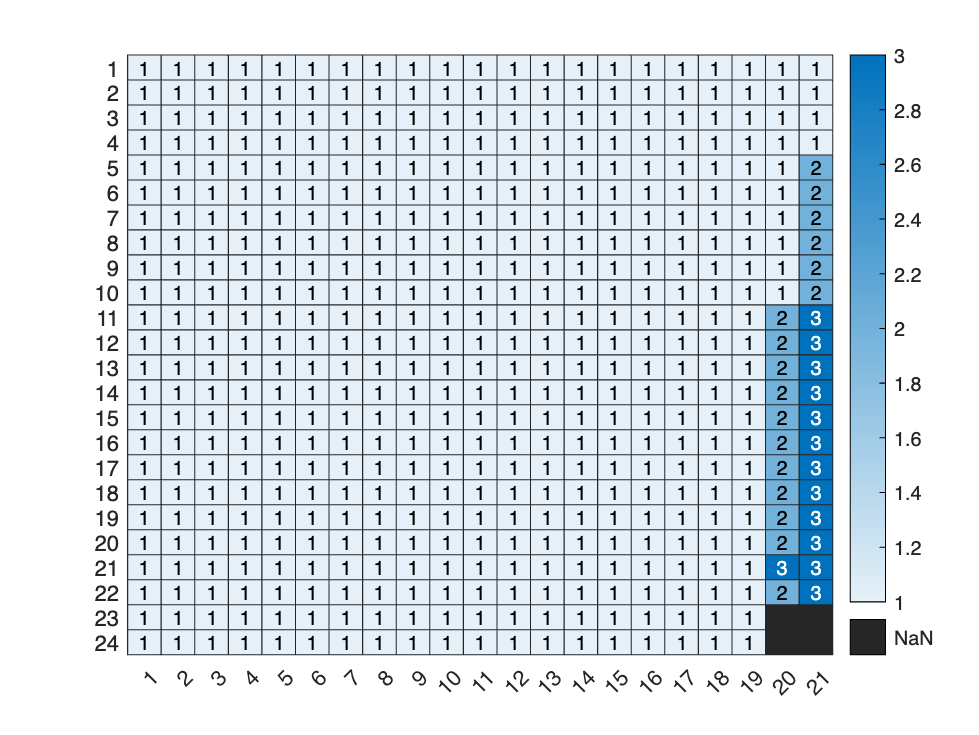

% plot the heatmap of the threshold line
% x axis is under different p1 conditions
% y axis is the photon count change
% number in the heatmap is the minimum line (photon count) not to detect
% that photon count induced lifetime change
figure
heatmap(detectable_line_all)

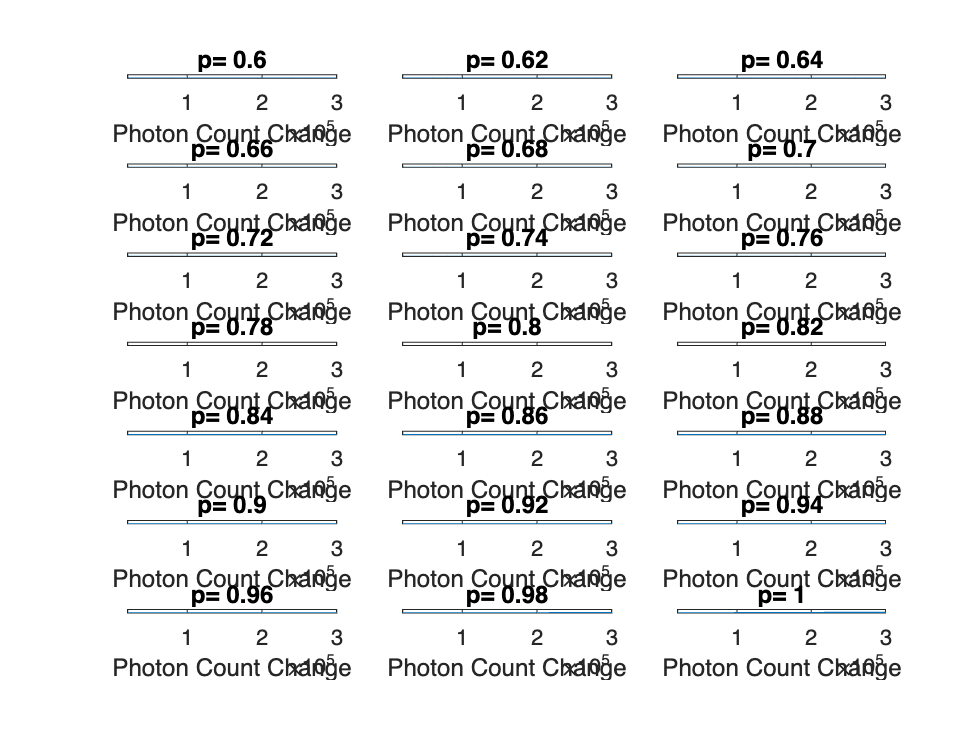

% plot the relationship between photon count change and the minimum photon
% count needed to tolerate that change. One curve for each p1 conditon.

for i=1:21
    photoncount_change_plot=(1:1:(24-sum(isnan(detectable_line_all(:,i)))))*20000;
    minimum_plot=detectable_line_all(:,i)*20000; % transform the minimum line to the photon count
    minimum_plot(isnan(minimum_plot))=[];
    subplot(7,3,i)
    plot(photoncount_change_plot,minimum_plot)
    xlabel('Photon Count Change')
    xlim([20000 300000])
    ylabel('Photon Count')
    ylim([20000 300000])
    title(['p= ',num2str(0.6+0.02*(i-1))])
end

The next session is to ask with sensor expression level change, what starting photon count is needed to still reflect biological change of lifetime. The way doing this is assume a certain amount of p1 change (depending on how much you expect for your biological change), then pool the samples with different photon count (but same p1) together to generate a new sample with new mean and new std. Based on new mean and new std it was checked whether that mean difference is still detectable.

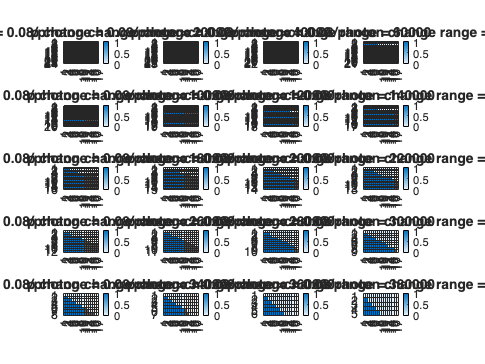

minimum_line_all_pool=[];
figure5=figure;
p1_change_steps=4; % defined p1 change

for k=1:20
    mean_all_pool=zeros(25-k, 21);
    std_all_pool=zeros(25-k, 21);
    for i=1:25-k
        for j=1:21
            
            mean_all_pool(i,j)=mean([mean_all(i,j) mean_all(i+k,j)]); % new mean
            
            eval(['sample1_pool=tau_empTrunc_',num2str(j),'(:,',num2str(i),');'])
            eval(['sample2_pool=tau_empTrunc_',num2str(j),'(:,',num2str(i+k),');'])

%             ['sample1_pool=tau_empTrunc_',num2str(j),'(:,',num2str(i),');']
%             ['sample2_pool=tau_empTrunc_',num2str(j),'(:,',num2str(i+k),');']
%             std_all_pool(i,j)=sqrt((std_all(i,j)^2+std_all(i+k,j)^2)/2);
            std_all_pool(i,j)=std([sample1_pool;sample2_pool]); % new std
%             mean([sample1_pool;sample2_pool])
%             mean([mean_all(i,j) mean_all(i+k,j)]) % check whether it's my
%             desired pooled population
        end
    end
%     subplot(5,2,k)
%     h=heatmap(mean_all_pool);
    
    

    subplot(5,4,k)
    heatmap(std_all_pool)
    
    for j=p1_change_steps % define p1 change as 0.06
        mean_all_pool_diff=zeros(25-k,21-j);
        for i=1:21-j
            mean_all_pool_diff(:,i)=mean_all_pool(:,i+j)-mean_all_pool(:,i); % mean difference between columns (p1)
        end
        
        diff=mean_all_pool_diff/3.96-std_all_pool(:,1:(21-j));
        diff_plot=diff;
        diff_plot(find(diff>=0))=1; % 1 detectable
        diff_plot(find(diff<0))=0; % 0 not detectable
        minimum_line_pool=[];
        for ii=1:21-j
            for jj=1:25-k
                if diff_plot(26-k-jj,ii)==0 % starting from the last line, move upwards, get the 1st line that is not detectable.
                    if jj==1
                        minimum_line_pool(ii)=NaN; % if the last line is already not detectable, then no valid threshold could be defined 
                        break
                    else
                        minimum_line_pool(ii)=27-k-jj; % line number plus 1 as the threshold line.
                        break
                    end
                end
            end
        end
        eval(['minimum_line_pool_',num2str(k),'=minimum_line_pool;'])
        minimum_line_all_pool=[minimum_line_all_pool; minimum_line_pool];

        subplot3=subplot(5,4,k);
        h=heatmap(diff_plot);
        h.Title=['p change = ',num2str(0.02*j),'/photon change range = ',num2str(20000*k)];
        h.ColorLimits=[0 1];
        
    end
end

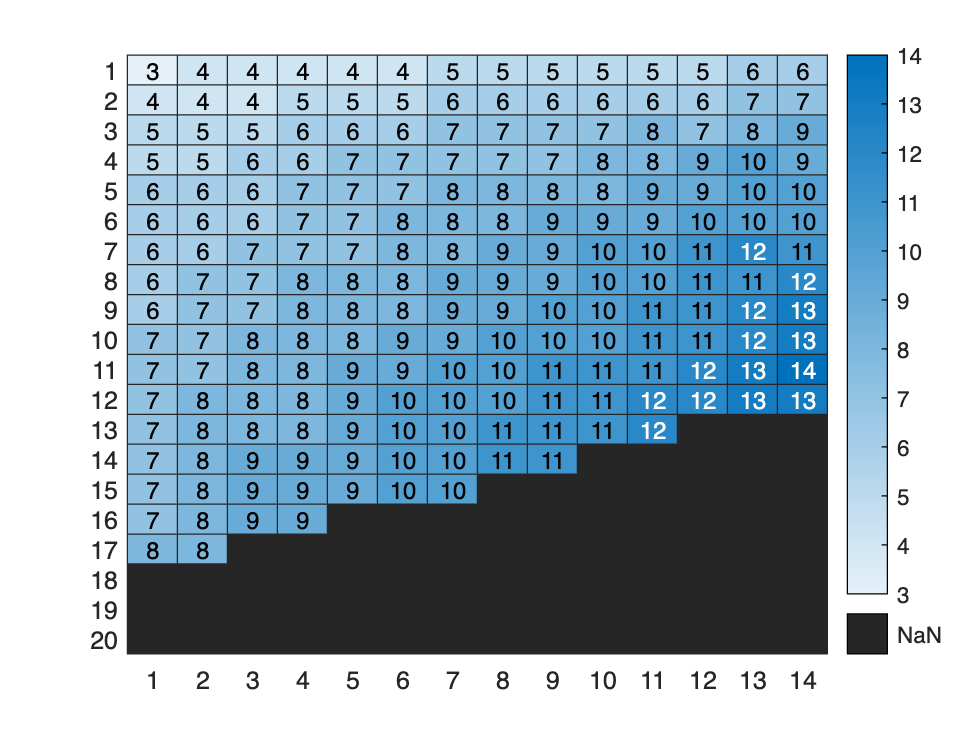

% plot the heatmap
% x-axis starting p1
% y axis different photon count change
% color or numbers: minimum photon count
figure
heatmap(minimum_line_all_pool)

Another question is till how to transform the p1 change to lifetime change. Here I'm trying to get a sense of with a certain amount of p1 change, how much lifetime change to expect under different photon counts across all different starting p1 value.

mean_changes=[];

for i=6:(16-p1_change_steps)
    eval(['mean_change=mean_all(:,',num2str(i+p1_change_steps),')-mean_all(:,',num2str(i),');'])
    mean_changes=[mean_changes mean_change];
end

mean(mean(mean_changes))

ans = 0.0553

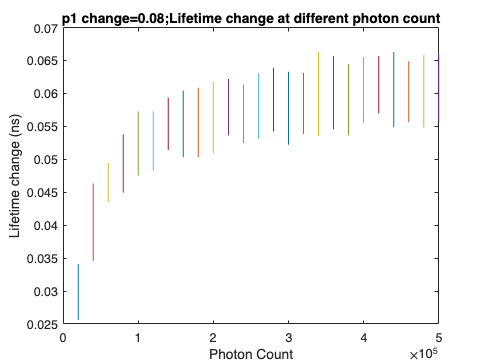

figure
for i=1:25
    plot([SS_samples(i),SS_samples(i)],[min(mean_changes(i,:)),max(mean_changes(i,:))])
    hold on
end
ylabel('Lifetime change (ns)')
xlabel('Photon Count')
title(['p1 change=',num2str(0.02*p1_change_steps),';Lifetime change at different photon count'])
hold off

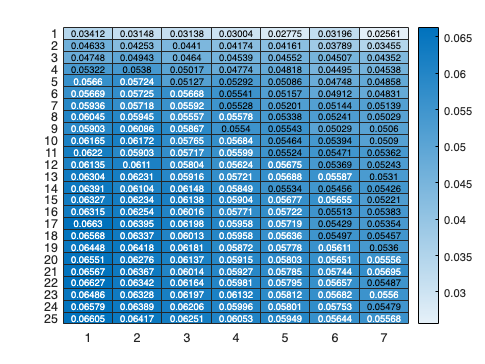

figure
heatmap(mean_changes)

% plot the relationship between photon count change and starting photon
% count threshold. One curve for each p1 condtions.
photon_change_pool=(1:1:k)*20000

photon_change_pool =        20000       40000       60000       80000      100000      120000      140000      160000      180000      200000      220000      240000      260000      280000      300000      320000      340000      360000      380000      400000


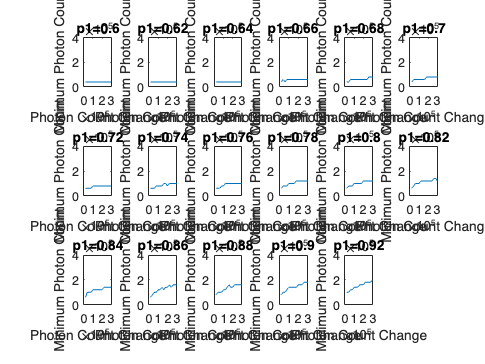

figure3=figure;

for i=1:21-p1_change_steps
    subplot(3,6,i,'parent',figure3)
    plot(photon_change_pool,minimum_line_all_pool(:,i)*20000);
    ylim([0 400000])
    title(['p1=',num2str(0.6+0.02*(i-1))])
    xlabel('Photon Count Change')
    ylabel('Minimum Photon Count')
    xlim([0 300000])
    

end

% analytical solutions to look at the relationship 

Relationship between p1 and average tau:

tau1=2.706;
tau2=0.2613;
tau3=2.4922;
tau4=0.4069;

p_plot=0.7:0.0002:0.9;
mean_tau=zeros(1,1001);
mean_auto=(tau3*tau3*p3+tau4*tau4*p4)/(tau3*p3+tau4*p4)

mean_auto =    1.853586267579859



for i=1:1001
    mean_tau(i)=(tau1*tau1*p_plot(i)+tau2*tau2*(1-p_plot(i)))/(tau1*p_plot(i)+tau2*(1-p_plot(i)));
end

line_x=[0.7 0.9];
line_y=[mean_tau(1) mean_tau(1001)];
(mean_tau(1001)-mean_tau(1))

ans =    0.071200133822631


(mean_tau(1001)-mean_tau(1))/0.2

ans =    0.356000669113157


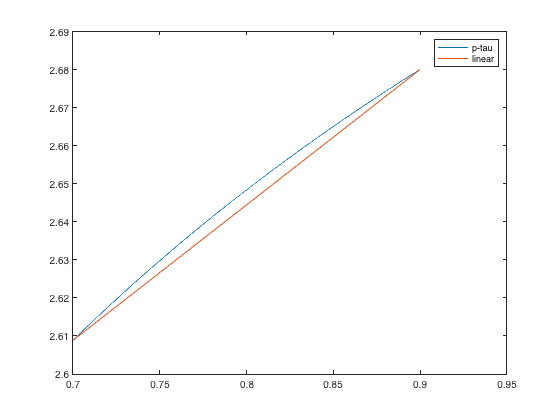


figure
plot(p_plot,mean_tau)
hold on
plot(line_x,line_y)
legend('p-tau','linear')

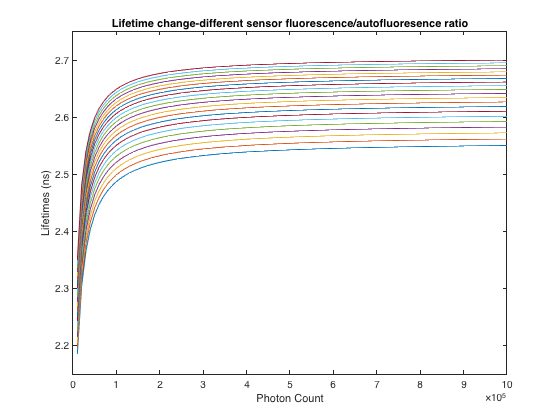

p1_test=p1_samples;


photonsize=(10000:10000:1000000)/20000;
for j=1:size(p1_test,2)
    mean_auto_ACh=zeros(1,size(photonsize,2));
    p1=p1_test(j);
    p2=1-p1;
    
    for i=1:100
        p1_ratio=(photonsize(i)/(1+photonsize(i)))*p1;
        p2_ratio=(photonsize(i)/(1+photonsize(i)))*p2;
        p3_ratio=(1/(1+photonsize(i)))*p3;
        p4_ratio=(1/(1+photonsize(i)))*p4;
    
        mean_auto_ACh(i)=(tau1*tau1*p1_ratio+tau2*tau2*p2_ratio+tau3*tau3*p3_ratio+tau4*tau4*p4_ratio)/...
            (tau1*p1_ratio+tau2*p2_ratio+tau3*p3_ratio+tau4*p4_ratio);
    %     mean_auto_ACh(i)=(photonsize(i)*mean_tau(500)+20000*mean_auto)/(photonsize(i)+20000);
    
    end
    eval(['mean_auto_ACh_',num2str(j),'=mean_auto_ACh;'])
end

figure
for i=1:size(p1_test,2)
    eval(['mean_auto_ACh_plot=mean_auto_ACh_',num2str(i),';'])
    plot(photonsize*20000,mean_auto_ACh_plot)
    hold on
end
title('Lifetime change-different sensor fluorescence/autofluoresence ratio')
ylim([2.15 2.75])
ylabel('Lifetimes (ns)')
xlabel('Photon Count')

p1_test=[0.7 0.78]

p1_test =    0.700000000000000   0.780000000000000



find(p1_samples==p1_test(1))

ans =      6


find(p1_samples==p1_test(2))

ans =     10


photonsize=(10000:10000:1000000)/20000;
for j=1:2
    mean_auto_ACh=zeros(1,size(photonsize,2));
    p1=p1_test(j);
    p2=1-p1;
    
    for i=1:100
        p1_ratio=(photonsize(i)/(1+photonsize(i)))*p1;
        p2_ratio=(photonsize(i)/(1+photonsize(i)))*p2;
        p3_ratio=(1/(1+photonsize(i)))*p3;
        p4_ratio=(1/(1+photonsize(i)))*p4;
    
        mean_auto_ACh(i)=(tau1*tau1*p1_ratio+tau2*tau2*p2_ratio+tau3*tau3*p3_ratio+tau4*tau4*p4_ratio)/...
            (tau1*p1_ratio+tau2*p2_ratio+tau3*p3_ratio+tau4*p4_ratio);
    %     mean_auto_ACh(i)=(photonsize(i)*mean_tau(500)+20000*mean_auto)/(photonsize(i)+20000);
    
    end
    eval(['mean_auto_ACh_',num2str(j),'=mean_auto_ACh;'])
end

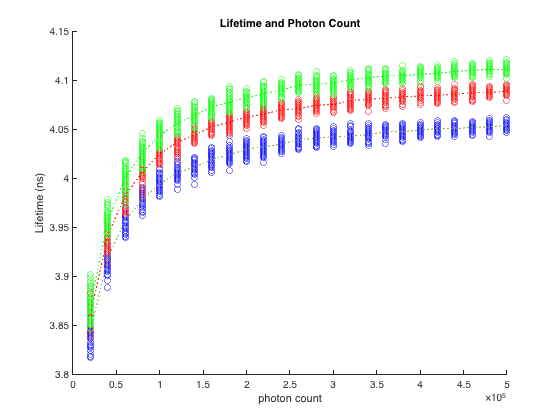

figure
% yyaxis left
for i=1:25
    scatter(zeros(1,50)+20000*i,tau_empTrunc_6(:,i),'blue')
    hold on

end
plot(SS_samples,mean_all(:,6),':')
ylim([3.8 4.15])
ylabel('Lifetime (ns)')
xlim([0 500000])

% yyaxis right
% plot(photonsize*20000,mean_auto_ACh_1,'-','Color','b')
% xlim([0 500000])
% ylim([2.22 2.65])

xlabel('photon count')
ylabel('Lifetime (ns)')
hold on

% yyaxis left
for i=1:25
    scatter(zeros(1,50)+20000*i,tau_empTrunc_10(:,i),'red')
    hold on

end
plot(SS_samples,mean_all(:,10),':','Color','red')

hold on

% yyaxis left
for i=1:25
    scatter(zeros(1,50)+20000*i,tau_empTrunc_13(:,i),'green')
    hold on

end
plot(SS_samples,mean_all(:,13),':','Color','green')
% yyaxis right
% f=plot(photonsize*20000,mean_auto_ACh_2,'-','Color','b')
% legend(f,'analytical')
title('Lifetime and Photon Count')

PhotonChange=[60000 160000]

PhotonChange =        60000      160000


find(SS_samples==PhotonChange(1))

ans = 3

find(SS_samples==PhotonChange(2))

ans = 8

mean_new_1=mean([mean_all(3,6) mean_all(8,6)])

mean_new_1 = 3.9878

std_new_1=sqrt((std_all(3,6)^2+std_all(8,6)^2)/2)

std_new_1 = 0.0084


mean_new_2=mean([mean_all(3,10) mean_all(8,10)])

mean_new_2 = 4.0174

std_new_2=sqrt((std_all(3,10)^2+std_all(8,10)^2)/2)

std_new_2 = 0.0076


mean_new=mean_new_2-mean_new_1

mean_new = 0.0296

mean_new/3.96-std_new_1

ans = -8.8692e-04

PhotonChange=[80000 180000]

PhotonChange =        80000      180000


find(SS_samples==PhotonChange(1))

ans = 4

find(SS_samples==PhotonChange(2))

ans = 9

mean_new_1=mean([mean_all(4,6) mean_all(9,6)])

mean_new_1 = 4.0014

std_new_1=sqrt((std_all(4,6)^2+std_all(9,6)^2)/2)

std_new_1 = 0.0071


mean_new_2=mean([mean_all(4,10) mean_all(9,10)])

mean_new_2 = 4.0321

std_new_2=sqrt((std_all(4,10)^2+std_all(9,10)^2)/2)

std_new_2 = 0.0075


mean_new=mean_new_2-mean_new_1

mean_new = 0.0307

mean_new/3.96-std_new_1

ans = 6.9381e-04

PhotonChange=[60000 160000]

PhotonChange =        60000      160000


find(SS_samples==PhotonChange(1))

ans = 3

find(SS_samples==PhotonChange(2))

ans = 8

mean_new_1=mean([mean_all(3,14) mean_all(8,14)])

mean_new_1 = 4.0413

std_new_1=sqrt((std_all(3,14)^2+std_all(8,14)^2)/2)

std_new_1 = 0.0084


mean_new_2=mean([mean_all(3,18) mean_all(8,18)])

mean_new_2 = 4.0623

std_new_2=sqrt((std_all(3,18)^2+std_all(8,18)^2)/2)

std_new_2 = 0.0088


mean_new=mean_new_2-mean_new_1

mean_new = 0.0210

mean_new/3.96-std_new_1

ans = -0.0031

PhotonChange=[80000 180000]

PhotonChange =        80000      180000


find(SS_samples==PhotonChange(1))

ans = 4

find(SS_samples==PhotonChange(2))

ans = 9

mean_new_1=mean([mean_all(4,14) mean_all(9,14)])

mean_new_1 = 4.0579

std_new_1=sqrt((std_all(4,14)^2+std_all(9,14)^2)/2)

std_new_1 = 0.0062


mean_new_2=mean([mean_all(4,18) mean_all(9,18)])

mean_new_2 = 4.0796

std_new_2=sqrt((std_all(4,18)^2+std_all(9,18)^2)/2)

std_new_2 = 0.0070


mean_new=mean_new_2-mean_new_1

mean_new = 0.0217

mean_new/3.96-std_new_1

ans = -7.3175e-04

PhotonChange=[280000 380000]

PhotonChange =       280000      380000


find(SS_samples==PhotonChange(1))

ans = 14

find(SS_samples==PhotonChange(2))

ans = 19

mean_new_1=mean([mean_all(14,14) mean_all(19,14)])

mean_new_1 = 4.1072

std_new_1=sqrt((std_all(14,14)^2+std_all(19,14)^2)/2)

std_new_1 = 0.0041


mean_new_2=mean([mean_all(14,18) mean_all(19,18)])

mean_new_2 = 4.1317

std_new_2=sqrt((std_all(14,18)^2+std_all(19,18)^2)/2)

std_new_2 = 0.0037


mean_new=mean_new_2-mean_new_1

mean_new = 0.0244

mean_new/3.96-std_new_1

ans = 0.0020

p1_test=[0.86 0.94]

p1_test =     0.8600    0.9400



find(p1_samples==p1_test(1))

ans = 14

find(p1_samples==p1_test(2))

ans = 18

photonsize=(10000:10000:1000000)/20000;
for j=1:2
    mean_auto_ACh=zeros(1,size(photonsize,2));
    p1=p1_test(j);
    p2=1-p1;
    
    for i=1:100
        p1_ratio=(photonsize(i)/(1+photonsize(i)))*p1;
        p2_ratio=(photonsize(i)/(1+photonsize(i)))*p2;
        p3_ratio=(1/(1+photonsize(i)))*p3;
        p4_ratio=(1/(1+photonsize(i)))*p4;
    
        mean_auto_ACh(i)=(tau1*tau1*p1_ratio+tau2*tau2*p2_ratio+tau3*tau3*p3_ratio+tau4*tau4*p4_ratio)/...
            (tau1*p1_ratio+tau2*p2_ratio+tau3*p3_ratio+tau4*p4_ratio);
    %     mean_auto_ACh(i)=(photonsize(i)*mean_tau(500)+20000*mean_auto)/(photonsize(i)+20000);
    
    end
    eval(['mean_auto_ACh_',num2str(j),'=mean_auto_ACh;'])
end

figure
yyaxis left
for i=1:25
    scatter(zeros(1,50)+20000*i,tau_empTrunc_14(:,i))
    hold on

end
plot(SS_samples,mean_all(:,14),':')
ylim([3.8 4.16])
ylabel('Lifetime (ns)')
yyaxis right
plot(photonsize*20000,mean_auto_ACh_1,'-','Color','b')
xlim([0 500000])
ylim([2.22 2.7])

xlabel('photon count')
ylabel('Lifetime (ns)')
hold on

yyaxis left
for i=1:25
    scatter(zeros(1,50)+20000*i,tau_empTrunc_18(:,i),'red')
    hold on

end
plot(SS_samples,mean_all(:,18),':','Color','red')
yyaxis right
f=plot(photonsize*20000,mean_auto_ACh_2,'-','Color','b')

f =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [10000 20000 30000 40000 50000 60000 70000 80000 90000 100000 110000 120000 130000 140000 150000 160000 170000 180000 190000 200000 210000 220000 230000 240000 250000 260000 270000 280000 290000 300000 310000 320000 330000 340000 … ]
              YData: [2.3300 2.4609 2.5221 2.5576 2.5808 2.5971 2.6092 2.6185 2.6260 2.6320 2.6370 2.6413 2.6449 2.6480 2.6507 2.6531 2.6553 2.6572 2.6589 2.6604 2.6619 2.6631 2.6643 2.6654 2.6664 2.6673 2.6682 2.6690 2.6697 2.6704 2.6710 2.6716 … ]

  Show all properties


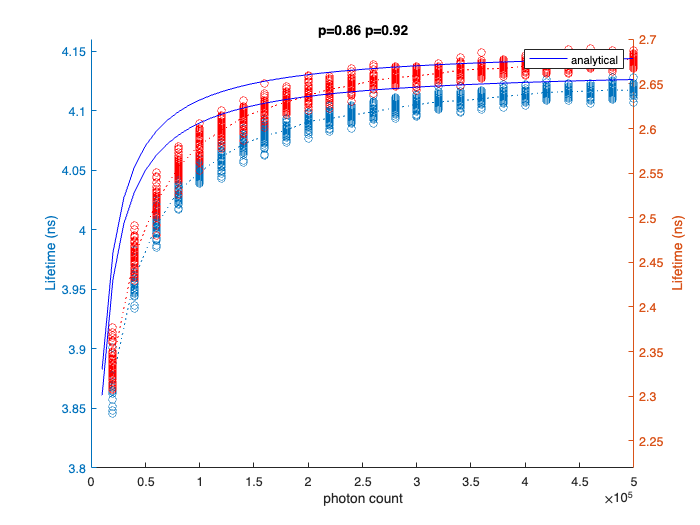

legend(f,'analytical')
title('p=0.86 p=0.92')

i1=find(photonsize==60000/20000)
i2=find(photonsize==400000/20000)
mean_auto_ACh_1(i1)
mean_auto_ACh_1(i2)
mean([mean_auto_ACh_1(i1) mean_auto_ACh_1(i2)])
mean_auto_ACh_2(i1)
mean_auto_ACh_2(i2)
mean([mean_auto_ACh_2(i1) mean_auto_ACh_2(i2)])


i3=find(photonsize==60000/20000)

photonsize =     0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000   25.0000


i1 = 6

i2 = 40

ans = 2.4592

ans = 2.5504

ans = 2.5048

ans = 2.5552

ans = 2.6385

ans = 2.5968

i4=find(photonsize==400000/20000)
mean_auto_ACh_1(i1)
mean_auto_ACh_1(i2)
mean([mean_auto_ACh_1(i1) mean_auto_ACh_1(i2)])
mean_auto_ACh_2(i1)
mean_auto_ACh_2(i2)
mean([mean_auto_ACh_2(i1) mean_auto_ACh_2(i2)])

sample1=60000;
sample2=160000;
sample3=260000;
sample4=360000;



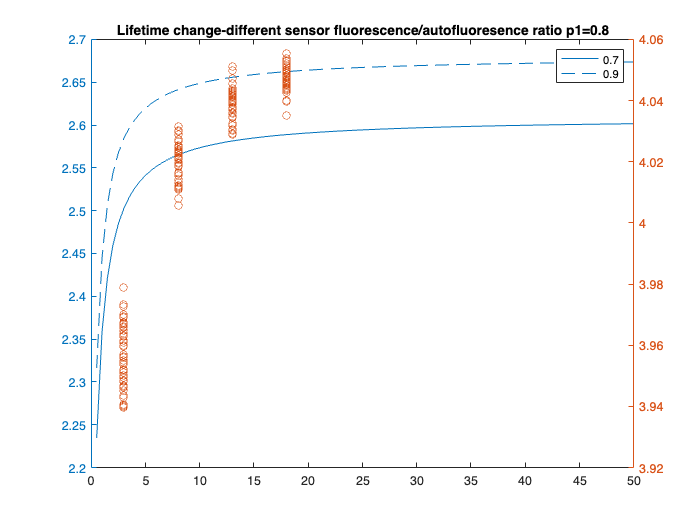

figure
yyaxis left
plot(photonsize,mean_auto_ACh_1)
hold on
plot(photonsize,mean_auto_ACh_2)
yyaxis right
scatter(zeros(1,50)+sample1/20000,tau_empTrunc_6(:,sample1/20000))
hold on
scatter(zeros(1,50)+sample2/20000,tau_empTrunc_6(:,sample2/20000))

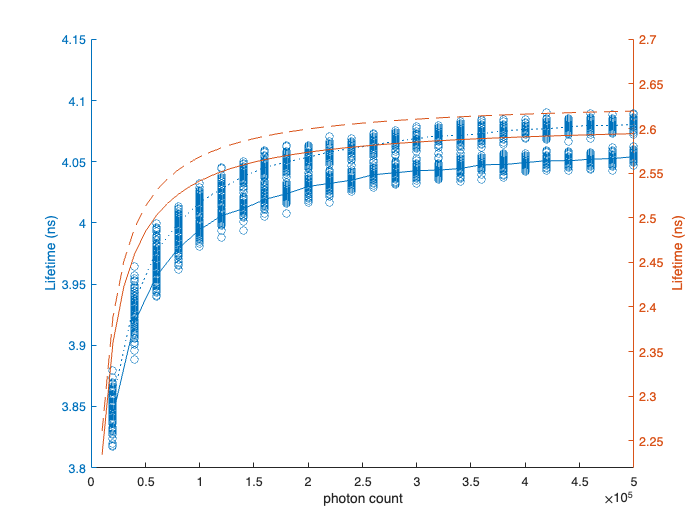

hold on
scatter(zeros(1,50)+sample3/20000,tau_empTrunc_6(:,sample3/20000))

hold on
scatter(zeros(1,50)+sample4/20000,tau_empTrunc_6(:,sample4/20000))
title('Lifetime change-different sensor fluorescence/autofluoresence ratio p1=0.8')
legend('0.7','0.9')

% A certain amount of lifetime lft_change is defined


% calculate the average fluorescence lifetime of autofluorescence
tau3=2.4922;
p3=0.2700;
tau4=0.4069;
p4=0.7300;
p1_samples=0.6:0.02:1.0;
AF=20000;
tau1=2.706;
tau2=0.2613;



autofluo_lft =    1.853586267579859


sample_autofluo_ratio=1:0.05:35;
sample_sizes=sample_autofluo_ratio*AF;

autofluo_lft=(tau3*tau3*p3+tau4*tau4*p4)/(tau3*p3+tau4*p4)
for j=1:size(p1_samples,2)
    p1=p1_samples(j);
    p2=1-p1;
    mean_lft=[];
    for i=1:size(sample_autofluo_ratio,2)
        ratio=sample_autofluo_ratio(i);
        mean_lft(i) = (tau1*tau1*p1*ratio + tau2*tau2*p2*ratio + tau3*tau3*p3 + tau4*tau4*p4)/(tau1*p1*ratio + tau2*p2*ratio + tau3*p3+tau4*p4);
    end
    
%     eval(['mean_lfts_',num2str(i),'(j)=mean_lft;'])
end


% lft=(tau1*tau1*p1 + tau2*tau2*p2)/(tau1*p1 + tau2*p2)
for i=1:size(SS_samples, 2)
    sample_size=SS_samples(i);
    mean_lft=[];
    for j=1:size(p1_samples,2)
        p1=p1_samples(j);
        p2=1-p1;
        mean_lft(j)=(tau1*tau1*p1 + tau2*tau2*p2)/(tau1*p1 + tau2*p2);
    end
%     figure
%     plot(p1_samples,mean_lft)
end

Unrecognized function or variable 'syms'.

lft_start=[];
for i=1:size(p1_samples,2)
    p1_start=p1_samples(i);
    lft_start(i)=(tau1*tau1*p1_start + tau2*tau2*(1-p1_start))/(tau1*p1_start + tau2*(1-p1_start));

end

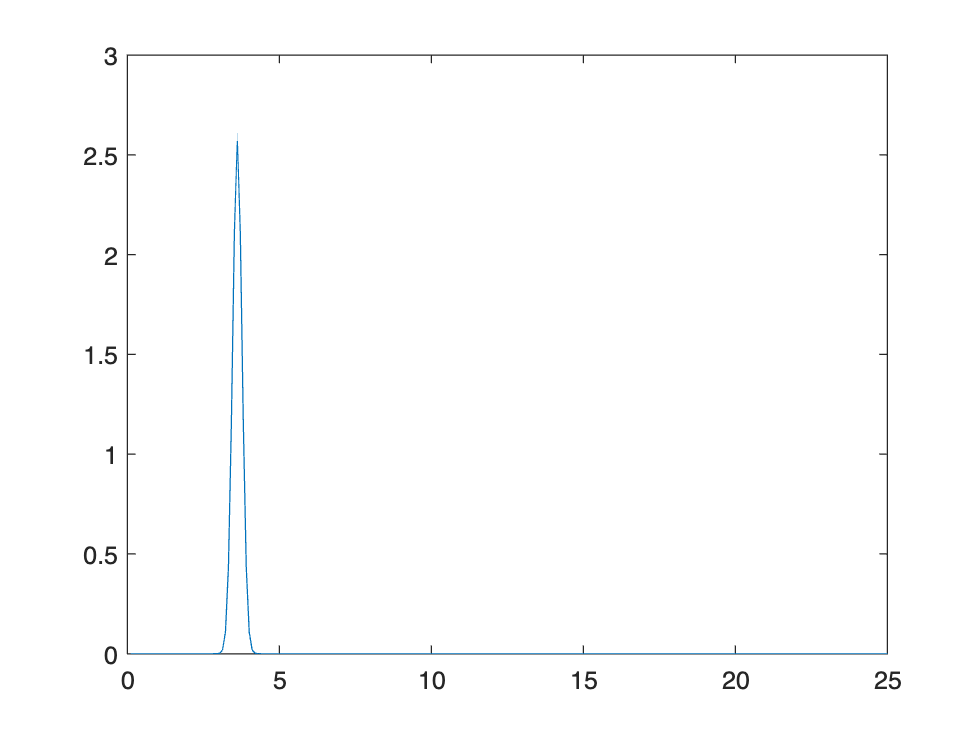

p1_end=[];
lft_change=0.02;

for i=1:size(p1_samples,2)
    syms tau1 tau2 lft_calc p1
    tau1=2.706;
    tau2=0.2613;

    lft_calc=lft_start(i)+lft_change;
    eqn=(tau1*tau1*p1 + tau2*tau2*(1-p1))/(tau1*p1 + tau2*(1-p1))==lft_calc
    S=solve(eqn,p1);
    p1_end(i)=double(S);
end

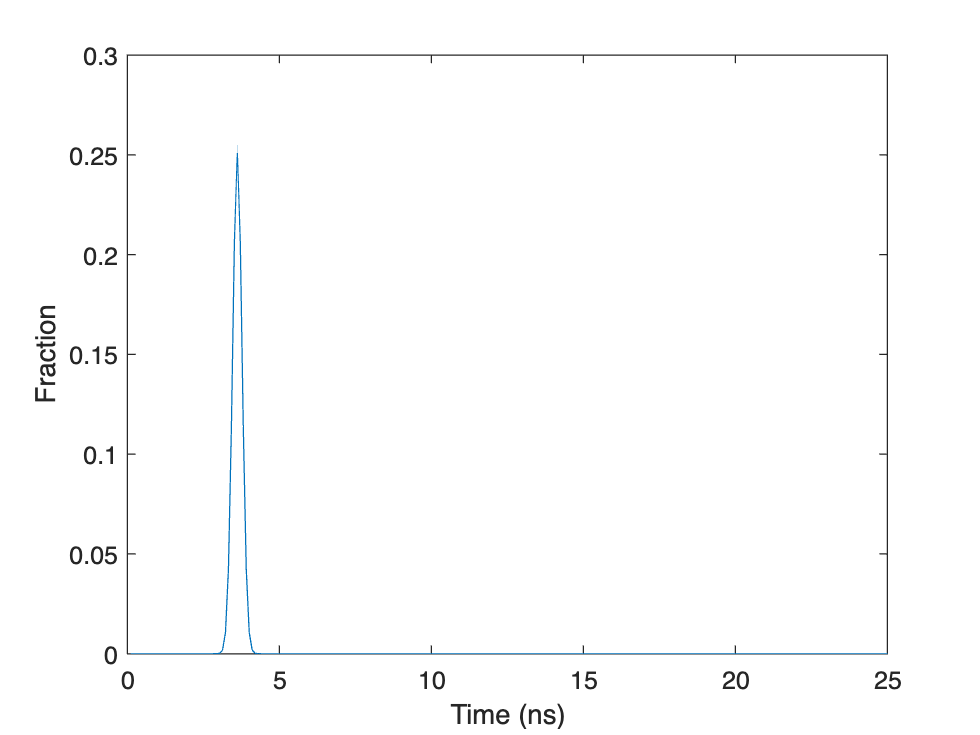

figure

plot(p1_samples)
hold on
plot(p1_end)

width=0.1554;
miu=3.6133;
x=1:1:256;
x=x*(25/256);
Gaussian_y=1/(width*sqrt(2*pi))*exp(-(x-miu).^2/(2*width^2));
figure
plot(x,Gaussian_y)
Gaussian_y=Gaussian_y/sum(Gaussian_y);
figure
plot(x,Gaussian_y)
Gaussian_y=Gaussian_y';
xlabel('Time (ns)')
ylabel('Fraction')

load('p1_end.mat')
p1_end(find(p1_end>1))=[];
p1_samples=p1_end;
AF=20000;
tau1=2.706;
tau2=0.2613;

SS_samples=20000:20000:500000;


global Gaussian_y

for i=5:11
    p1=p1_samples(i);
    p2=1-p1;
    PopulationName=['Simulation_02102022_FLP_population_',num2str(p1),'.mat'];
    GenPop256_FLP(100000, p1, p2, tau1, tau2, PopulationName);
    for j=1:25
        SS=SS_samples(j);
        mkdir([num2str(SS),'_',num2str(p1)])
        for k=1:50
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            FLIMsim256_FLP(SS,AF,PopulationName,samplename)
        end
    end
end


cd('/Users/pingchuanma/Desktop/ChenLab_Data/simulation_FLP_20220326')

h =   HeatmapChart with properties:

        XData: {17×1 cell}
        YData: {25×1 cell}
    ColorData: [25×17 double]

  Show all properties


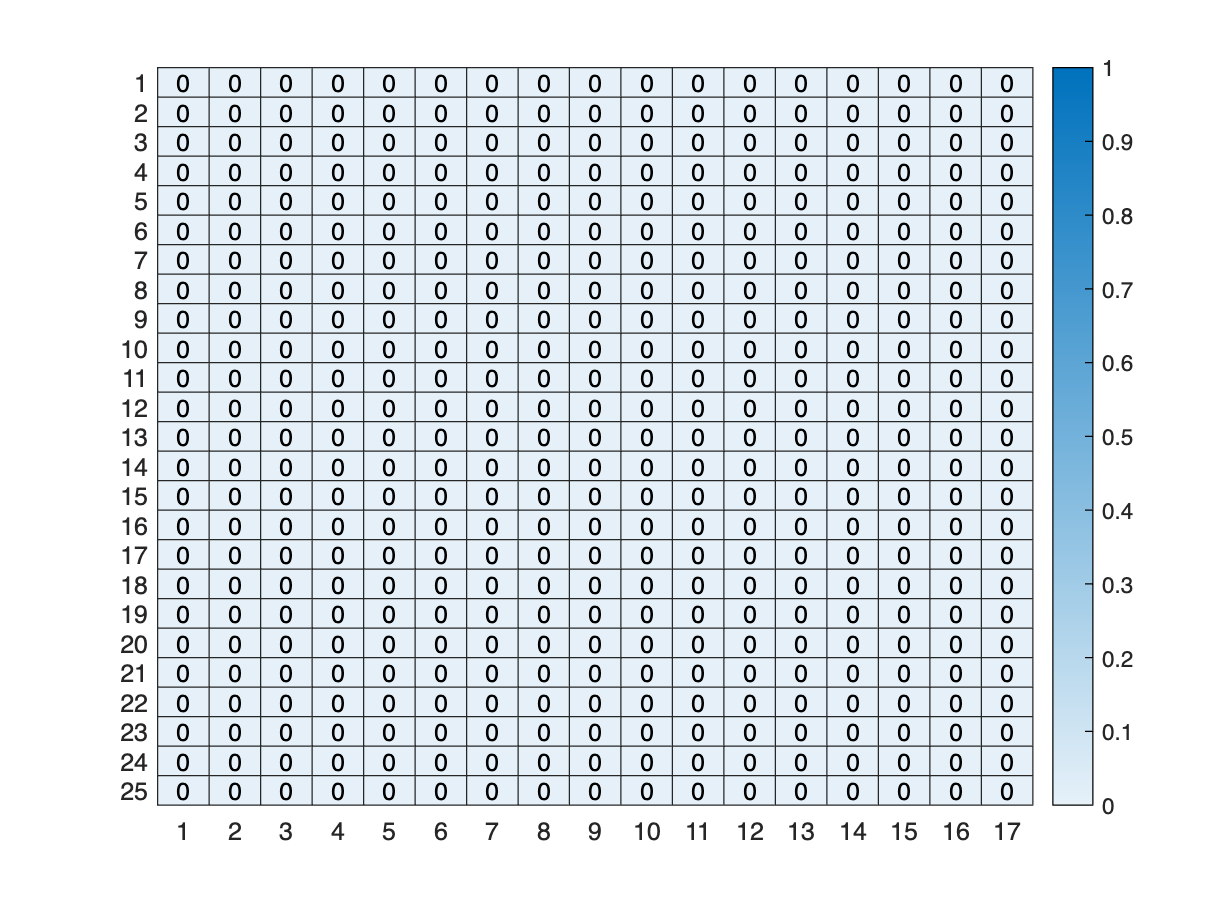

ch=1;

for i=1:17
    p1=p1_samples(i);
 

    for j=1:25
        SS=SS_samples(j);
%         mkdir([num2str(SS),'_',num2str(p1),'_auto'])
        
        tau_avg=[];
        tau_avgTrunc=[];
        tau_empTrunc=[];
        photoncount=[];
        p1_sim=[];
        chi2=[];
        beta2=[];
        beta4=[];
        beta5=[];
        beta6=[];
        lifetime_histograms=[];
        peak_beforeC=[];
        peak_afterC=[];
        peak_withauto=[];
        
        for k=1:50
            
            AFname=['20000_AF/',num2str(k),'_auto.mat'];
            load(AFname);
            n_auto=n2';
            
            samplename=[num2str(SS),'_',num2str(p1),'/',num2str(k),'_noauto.mat'];
            load(samplename)
            n_ACh=n2';
            spc.lifetimes{1}=n_ACh+n_auto+6;
            
            
            spc_fitexp2gaussGY(ch);
%             spc_adjustTauOffset(1);
            
            
            photoncount(k)=sum(spc.lifetimes{1});
            p1_sim(k)=spc.fits{ch}.beta1/(spc.fits{ch}.beta1+spc.fits{ch}.beta3);
            tau_avg(k)=spc.fits{ch}.avgTau; % mean Tau calculated from fit
            tau_avgTrunc(k)=spc.fits{ch}.avgTauTrunc;
            tau_empTrunc(k)=spc.fits{ch}.EmpTauTrunc;
            chi2(k)=spc.fits{ch}.redchisq;
            beta2(k)=spc.fits{ch}.beta2;
            beta4(k)=spc.fits{ch}.beta4;
            beta5(k)=spc.fits{ch}.beta5;
            beta6(k)=spc.fits{ch}.beta6;
            lifetime_histograms=[lifetime_histograms spc.lifetimes{1}];
            peak_beforeC(k)=mean(find(n1==max(n1)));
            peak_afterC(k)=mean(find(n2==max(n2)));
            peak_withauto(k)=mean(find(spc.lifetimes{1}==max(spc.lifetimes{1})));
            
        end
        
        photoncount=transpose(photoncount);
        tau_avg=transpose(tau_avg);
        tau_avgTrunc=transpose(tau_avgTrunc);
        tau_empTrunc=transpose(tau_empTrunc);
        p1_sim=transpose(p1_sim);
        chi2=transpose(chi2);
        beta2=transpose(beta2);
        beta4=transpose(beta4);
        beta5=transpose(beta5);
        beta6=transpose(beta6);
        
        result_name=[num2str(SS),'_',num2str(p1),'_result.mat'];
        save(result_name,'photoncount', 'tau_avg','tau_avgTrunc','tau_empTrunc', 'p1_sim','chi2','beta2','beta4','beta5','beta6','lifetime_histograms')
    end
end



load('p1_end.mat')
p1_samples1=p1_end;
p1_samples2=0.6:0.02:1.0;
p1_samples2=p1_samples2(1:17);
ttest_results=ones(25,17);

for j=1:25
    SS=SS_samples(j);
    eval(['tau_empTrunc_',num2str(SS),'1=[];'])
    eval(['tau_empTrunc_',num2str(SS),'2=[];'])
    
    for i=1:17
        p1=p1_samples1(i);
        p2=p1_samples2(i);

        result_name1=[num2str(SS),'_',num2str(p1),'_result.mat'];
        load(result_name1);
        eval(['tau_empTrunc_',num2str(SS),'1=[tau_empTrunc_',num2str(SS),'1 tau_empTrunc];'])
        test1=tau_empTrunc;

        result_name2=[num2str(SS),'_',num2str(p2),'_result.mat'];
        load(result_name2);
        eval(['tau_empTrunc_',num2str(SS),'2=[tau_empTrunc_',num2str(SS),'2 tau_empTrunc];'])
        test2=tau_empTrunc;
        test_result=ttest2(test1,test2);
        if test_result==1
            ttest_results(j,i)=0;
        end
    end
end

figure
h=heatmap(ttest_results)
h.ColorLimits=[0 1];

